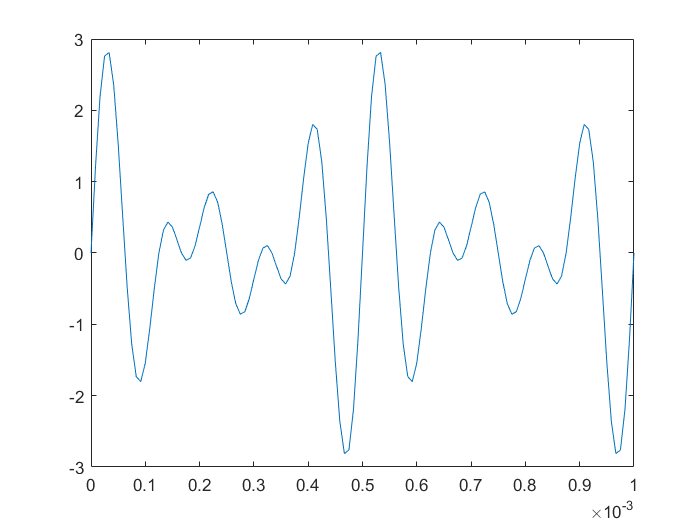

f1 = 10000;
f2 = 8000;
f3 = 6000;
fs = 120000; %sampling
fc = 8000; %cutoff
nfft = 2^nextpow2(8000); %num transform points

f = ((0:nfft/2-1)*fs/nfft); %f vector
t = 0:1/(fs):1e-3 ;%t vector
x = sin(2*pi*t*f1);
x2 = sin(2*pi*t*f2);
x3 = sin(2*pi*t*f3);
a = x + x2 + x3; %sum of signals
plot(t,a)

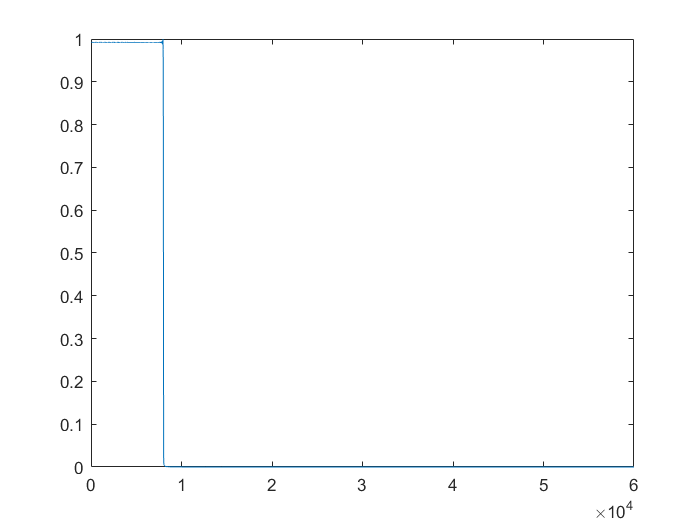



% make windowed filter
n = 1:nfft+1;
N = nfft+1;
fil = sinc(2*(fc/fs)*(n-((N-1)/2)));
win = 0.42 - .5 * cos((2*pi*n)/N-1) + 0.08 * cos((4*pi*n)/N-1);
filwin = fil.*win;
filwin = fft(filwin, nfft);
filwin = abs(filwin/max(abs(filwin(10:end))));
plot(f, filwin(1:length(filwin)/2))

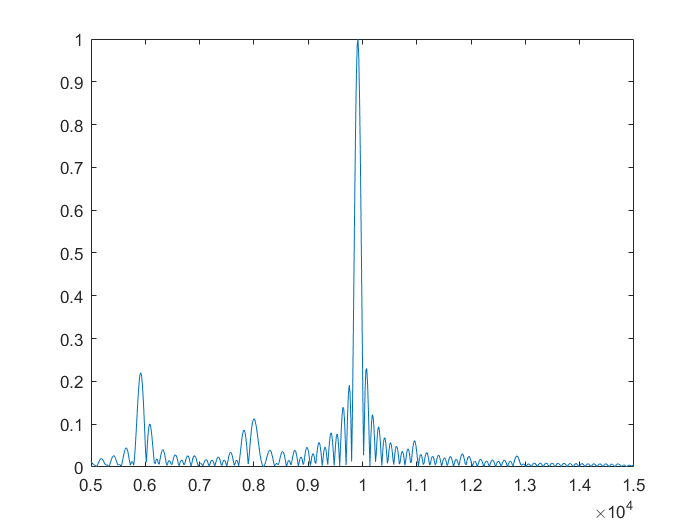


num = 0.5*(length(a)-1)+2; % subtracted from nfft*3 to pad proper amount
a = padarray(a,[0,(nfft*3) - num],'circular');
a(length(a)+1) = 0; % added a few more zeros to get len(a) divisible by 6
a(length(a)+1) = 0;
a(length(a)+1) = 0;
%Split signal into six subfilters- becomes a 1X6 cell
b = mat2cell(a, 1, [length(a)/6 length(a)/6 length(a)/6 length(a)/6 length(a)/6 length(a)/6]);
fftOut = zeros([1,nfft]);

%multiply signals by windowed filter and add to output
for i = 1:length(b)
    b{1,i} = b{1,i} .* filwin;
    fftOut = fftOut + b{1,i};
end

fftOut = fft(fftOut,nfft);
fftOut = fftOut(1:nfft/2);
plot(f,abs(fftOut/max(abs(fftOut(10:end)))))
xlim([5000,15000])